# Plot prediction-outcome correaltion vs. number of components (SCR/ECG models combined)

clear;
close all;

basedir = '/Users/clinpsywoo/Dropbox (CANLAB)/C_CRB_analysis/analysis/MWW_inprep/scripts';
cd(basedir);

load('../data/CRB_dataset_SCR_lpf5Hz_DS25Hz_011516.mat');

figdir = '../figures';
datdir = '../data';

scr = load(fullfile(datdir, 'SCR_prediction_dat_112816.mat'));
ecg = load(fullfile(datdir, 'ECG_prediction_dat_112816.mat'));

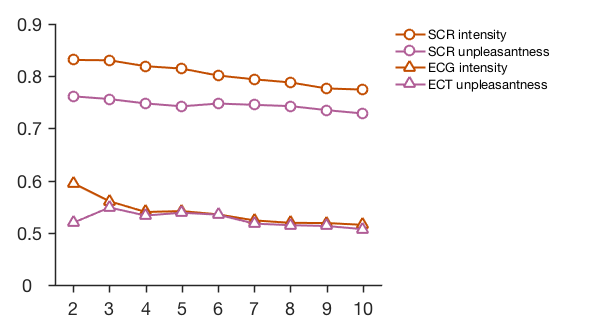

x = [scr.pred_outcome_r.int' scr.pred_outcome_r.unp' ecg.pred_outcome_r.int' ecg.pred_outcome_r.unp'];

create_figure('pred_outcome_r');

cols = [0.7608    0.3020         0
    0.6902    0.3647    0.5882
    0.7608    0.3020         0
    0.6902    0.3647    0.5882];

for i = 1:2
    plot(x(:,i), '-o', 'color', cols(i,:), 'linewidth', 2, 'MarkerFaceColor', 'w', 'MarkerSize', 10); 
%     plot(x(1,i), 's', 'color', cols(i,:), 'linewidth', 2.5, 'MarkerFaceColor', 'y', 'MarkerSize', 13);
end

for i = 3:4
    plot(x(:,i), '-^', 'color', cols(i,:), 'linewidth', 2, 'MarkerFaceColor', 'w', 'MarkerSize', 10); 
%     if i == 3, plot(x(1,i), 's', 'color', cols(i,:), 'linewidth', 2.5, 'MarkerFaceColor', 'y', 'MarkerSize', 13); end
%     if i == 4, plot(2, x(2,i), 's', 'color', cols(i,:), 'linewidth', 2.5, 'MarkerFaceColor', 'y', 'MarkerSize', 13); end
end

set(gcf, 'Position', [360   378   594   320]);
set(gca, 'linewidth', 1.5, 'fontsize', 18, 'tickdir', 'out', 'TickLength', [.02 .02],...
    'xlim', [.5 9.5], 'ylim', [.4 .9], 'yticklabel', [0 0.5 0.6 0.7 0.8 0.9], 'xtick', 1:9, 'xticklabel', {'2', '3', '4', '5', '6', '7', '8', '9', '10'});

h = legend('SCR intensity', 'SCR unpleasantness', 'ECG intensity', 'ECT unpleasantness', 'Location','NorthEastOutside');
h.FontSize = 13;
h.Box = 'off';

savename = fullfile(figdir, 'prediction_outcome_r_ncomp.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);